clc
clear

set(groot, 'defaultAxesTickLabelInterpreter','latex'); 
set(groot, 'defaultLegendInterpreter','latex');
set(groot, 'defaultTextInterpreter','latex');

% constants
CD_min = 0.014; % Minimum drag coefficient
k = 0.07; % Induced drag factor
rho = 1.225; % Air density [kg/m^3]
V_infinity = 30; % Freestream velocity [m/s]
V_Vertical = 2.23; % Vertical velocity [m/s]
q = 0.5 * rho * V_infinity^2; % Dynamic pressure

% Wing loading range [N/m^2]
W_S = linspace(10, 700, 1000); 



## Climb constraint

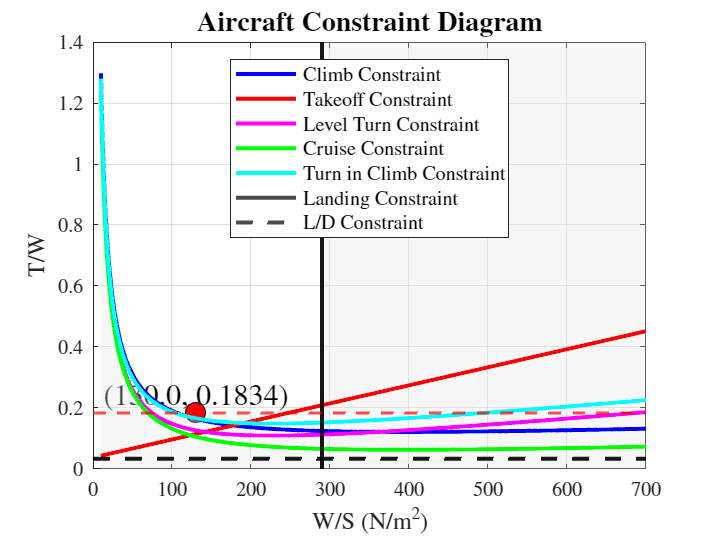

T_W_Climb = (V_Vertical / V_infinity) + (q ./ W_S) * CD_min + (k * W_S) ./ q;

% Service ceiling constraint
V_Vertical_Max = 2;
T_W_Ceiling = (1.667 / V_Vertical_Max) + (q./W_S)*CD_min + (k/q)*(W_S);

% Takeoff ground run constraint
g = 9.81;
CL_max = 1.7;
S_G = 100;
CD_TO = 0.02;
mu_Takeoff = 0.04;
CL_TO = 0.7;
T_W_Takeoff = (1.21/(g*rho*CL_max*S_G))*(W_S) + (0.605/CL_max)*(CD_TO-(mu_Takeoff*CL_TO)) + mu_Takeoff;

% Level turn constraint
angle = deg2rad(55); % Bank angle [rad]
n = 1/cos(angle); % Load factor
T_W_Turn = q*((CD_min./(W_S))+k*((n/q)^2)*W_S);

% Climbing turn constraint
P_S = 1.5; % Climb [m/s]
T_W_Turn_Climb = q*((CD_min./W_S) + (k*(n/q)^2)*(W_S)) + P_S/V_infinity;

% Cruise L/D constraint
Lift_Drag = 30;
T_W_LD = 1/(Lift_Drag);

% Cruise airspeed constraint
T_W_Cruise = ((q*CD_min)*(1./W_S)) + k*(1/q).*(W_S);

%% Landing constraint calculation
% Initialize parameters
h_obst = 0;
roll_time = 2;
A = rho * CL_max;
mu_Landing = 0.3;
CD_Landing = 0.3;
CL_Landing = 0.2;

% Iterative solution for landing constraint
W_S_Landing = 500; % Initial guess [N/m^2]
for iter = 1:1000
    term1 = 19.08 * h_obst;
    term2 = 0.007923 + 1.556 * roll_time * (A / W_S_Landing);
    term3 = 1.21 / (g * ((0.605 / CL_max) * (CD_Landing - mu_Landing * CL_Landing) + mu_Landing));
    S_Landing = term1 + (term2 + term3) * (W_S_Landing / A);
    
    if S_Landing < 50
        break;
    else
        W_S_Landing = W_S_Landing - 10;
    end
end

%% Plotting with LaTeX fonts
figure(1);
plot(W_S, T_W_Climb, 'b-', 'LineWidth', 2); hold on;
plot(W_S, T_W_Takeoff, 'r-', 'LineWidth', 2);
plot(W_S, T_W_Turn, 'm-', 'LineWidth', 2);
plot(W_S, T_W_Cruise, 'g-', 'LineWidth', 2);
plot(W_S, T_W_Turn_Climb, 'c-', 'LineWidth', 2);
xline(W_S_Landing, 'k-', 'LineWidth', 2);
yline(T_W_LD, 'k--', 'LineWidth', 2);

designPointX = 130;
designPointY = 0.1834;
plot(designPointX, designPointY, 'ko', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

text(designPointX, designPointY, sprintf('(%.1f, %.4f)', designPointX, designPointY), ...
    'VerticalAlignment', 'bottom', ...  % Places text above the point
    'HorizontalAlignment', 'center', ... % Centers text horizontally
    'FontSize', 15, ...
    'Color', 'k', ...
    'Interpreter', 'latex');
figure(1);


fill([W_S_Landing W_S_Landing max(W_S) max(W_S)], ...
     [0 max(ylim) max(ylim) 0], [0.9 0.9 0.9], 'EdgeColor', 'none', 'FaceAlpha', 0.3);
hold on;

[~, idx] = min(abs(W_S - W_S_Landing)); 
fill([W_S(1:idx) W_S(idx:-1:1)], ...
     [T_W_Turn_Climb(1:idx) zeros(1,idx)], [0.9 0.9 0.9], 'EdgeColor', 'none', 'FaceAlpha', 0.3);

% Plot all constraints
plot(W_S, T_W_Climb, 'b-', 'LineWidth', 2);
plot(W_S, T_W_Takeoff, 'r-', 'LineWidth', 2);
plot(W_S, T_W_Turn, 'm-', 'LineWidth', 2);
plot(W_S, T_W_Cruise, 'g-', 'LineWidth', 2);
plot(W_S, T_W_Turn_Climb, 'c-', 'LineWidth', 2);
xline(W_S_Landing, 'k-', 'LineWidth', 2);
yline(T_W_LD, 'k--', 'LineWidth', 2);

xlabel('W/S (N/m$^2$)', 'FontSize', 12);
ylabel('T/W', 'FontSize', 12);
title('\textbf{Aircraft Constraint Diagram}', 'FontSize', 14);
grid on;
yline(0.1835, 'r--', 'LineWidth', 1.5);
% yline(0.2446, 'r--', 'LineWidth', 1.5);

hold off;
xlabel('W/S (N/m$^2$)', 'FontSize', 12);
ylabel('T/W', 'FontSize', 12);
title('\textbf{Aircraft Constraint Diagram}', 'FontSize', 14);
grid on;

legend({'Climb Constraint', 'Takeoff Constraint', 'Level Turn Constraint', ...
       'Cruise Constraint', 'Turn in Climb Constraint', 'Landing Constraint', ...
       'L/D Constraint'}, 'Location', 'best', 'FontSize', 10);

hold off;